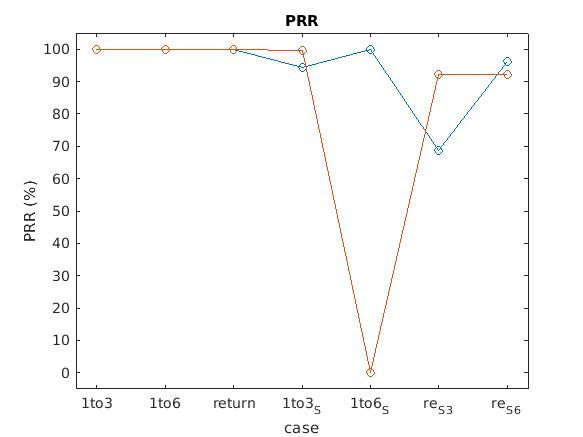


clear;
sentFile = [
    "1_sent.dat"
    "2_sent.dat"
    "3_sent_3.dat"
    "5_sent.dat"
    "6_sent.dat"
    "4_sent_6.dat"
    "4_sent_3.dat"

    ];

sent_cnt = length(sentFile);

recvFile =  [
    "1_recv.dat"
    "2_recv.dat"
    "3_recv.dat"
    "5_recv.dat"
    "6_recv.dat"
    "4_recv.dat"

    ];
recv_cnt = length(recvFile);
xlabel_sent = {'1to3','1to6','return','1to3_S','1to6_S',"re_S_3","re_S_6"};

xlabels = {'1to3','1to6','return','1to3_S','1to6_S',"return_S"};

mean_nretx = [];
mean_result = [];
mean_delay = [];
mean_diversity = [];
mean_snr= [] ;
mean_rssi = [];

mean_recv_len = [];
for cnt = 1:1:sent_cnt
    
    sent_array= csvread(sentFile(cnt));
    mean_nretx = [mean_nretx mean(sent_array(:,2))];
    mean_result = [mean_result mean(sent_array(:,3))];
    mean_delay = [mean_delay mean(sent_array(:,4))];
end

for cnt = 1: 1: recv_cnt
    recv_array = csvread(recvFile(cnt));

    mean_diversity = [mean_diversity mean(recv_array(:,2))];
    mean_snr = [mean_snr mean(recv_array(:,3))];
    mean_rssi = [mean_rssi mean(recv_array(:,4))];
    
    mean_recv_len = [mean_recv_len length(recv_array')];

end
mean_recv_len(1,5) = 0;
xlength = length(sentFile);
mean_recv_len = [mean_recv_len mean_recv_len(1,6)];
plot([mean_result*100; mean_recv_len*0.1]',"-o");
ylim([-5 105])
xlim([0.7 (xlength + 0.3)])
xticks([1:xlength+1])
xticklabels(xlabel_sent)
xlabel("case")
ylabel("PRR (%)")
title("PRR");

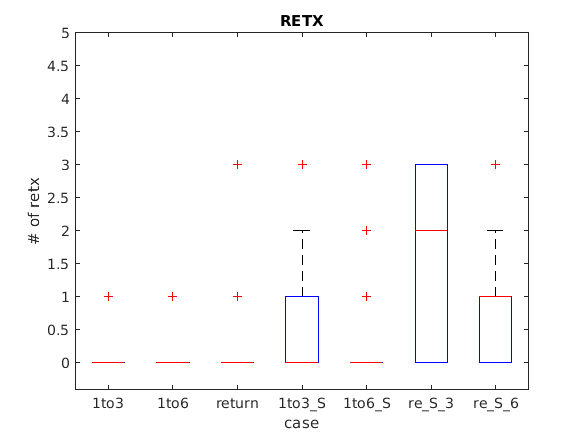





for cnt = 1:1:recv_cnt
    csvread(recvFile(cnt));
    recv_data(cnt) = {csvread(recvFile(cnt))};
end

for cnt = 1:1:sent_cnt
    sent_data(cnt)= {csvread(sentFile(cnt))};
end



sent_array = cell2mat(sent_data);

recv_array = [];
for cnt = 1:1:recv_cnt
    temp_data =cell2mat(recv_data(cnt));
    while length(temp_data) < 950
        temp_data = [temp_data ;temp_data];
    end
    temp_data = temp_data(1:950,:);
    recv_array = [recv_array temp_data];
end


nretx = [];
result = [];
delay = [];
diversity = [];
snr= [] ;
rssi = [];

for cnt = 1:1:sent_cnt
    nretx = [nretx sent_array(:,2 + 4*(cnt-1))];
    result = [result sent_array(:,3 + 4*(cnt-1))];
    delay = [delay sent_array(:,4*cnt)];
end
for cnt = 1:1:recv_cnt
    diversity = [diversity recv_array(:,2 + 4*(cnt -1))];
    snr = [snr recv_array(:,3 + 4*(cnt -1))];
    rssi = [rssi recv_array(:,4*cnt)];
end



boxplot(nretx);
title("nretx");
ylim([-0.4 5])
xticks([1:xlength+1])
xticklabels(xlabel_sent)
xlabel("case")
ylabel("# of retx")
title("RETX");

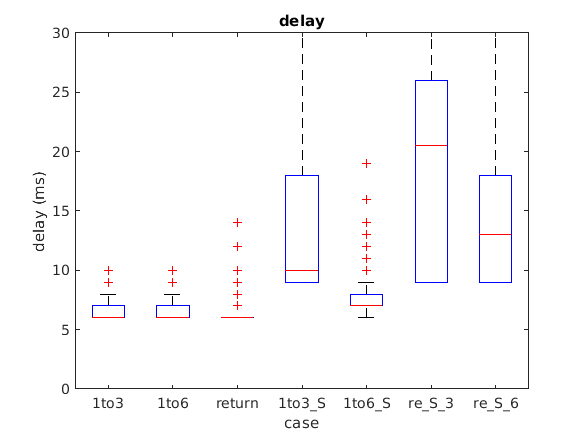




boxplot(delay);
title("delay");
ylim([0 30])
xticks([1:xlength + 1])
xticklabels(xlabel_sent)
xlabel("case")
ylabel("delay (ms)")

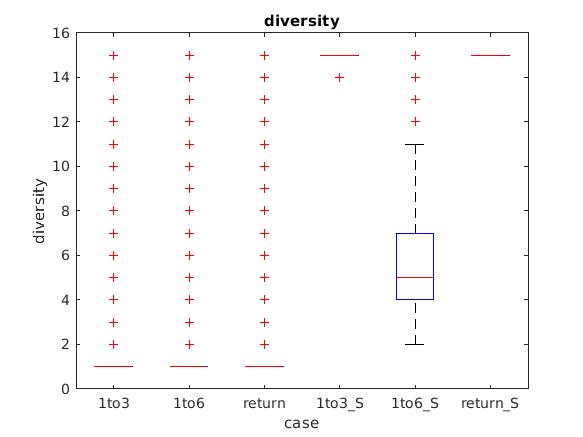



boxplot(diversity);
title("diversity");
ylim([0 16])
xticks([1:xlength])
xticklabels(xlabels)
xlabel("case")
ylabel("diversity")

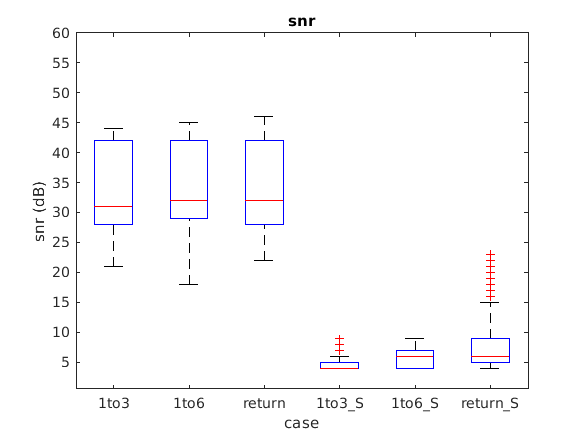



boxplot(snr);
title("snr");
ylim([0.5 60])
xticks([1:xlength])
xticklabels(xlabels)
xlabel("case")
ylabel("snr (dB)")

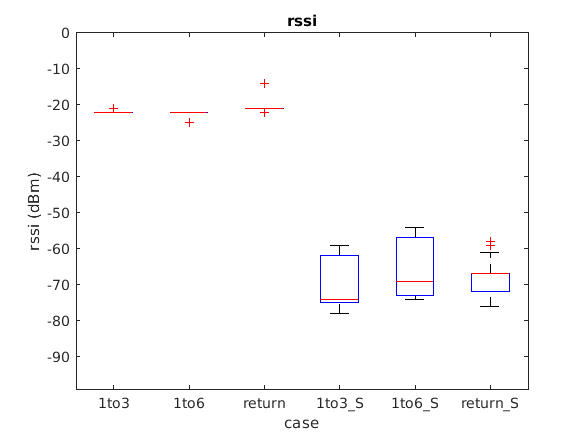




boxplot(rssi);
title("rssi");
ylim([-99 0])
xticks([1:xlength])
xticklabels(xlabels)
xlabel("case")
ylabel("rssi (dBm)")